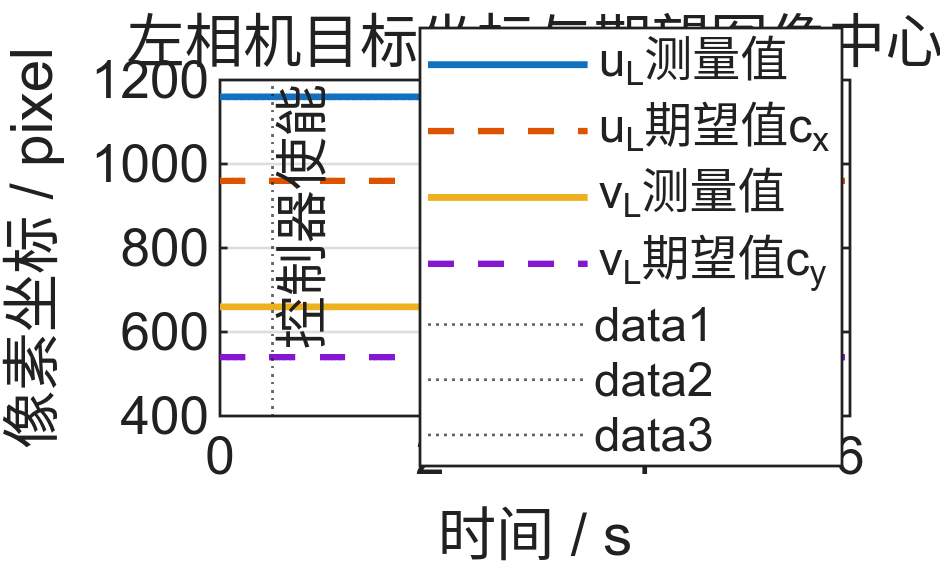

%% PLOT_STEREO_IBVS_SIM_STAGE1_RESULTS
% 代码作用：
% 运行stereo_ibvs_sim_stage1离线仿真，并绘制Stage 1的四组结果：
% 1. 左相机目标像素坐标与期望图像中心；
% 2. 左相机归一化中心误差；
% 3. 七个关节速度命令；
% 4. 控制链路关键状态。
%
% 输入参数含义：
% 本脚本没有函数输入参数。
% 运行前需要已经生成：
% stereo_ibvs_sim_stage1.slx
%
% 输出参数含义：
% 本脚本没有函数输出参数。
% 运行后会生成四个Figure，并在工作区保留仿真结果out。

%% 1. 查找并打开仿真模型
modelName = 'stereo_ibvs_sim_stage1';

modelFile = which([modelName '.slx']);

if isempty(modelFile)
    candidateFile = fullfile(pwd,'sim',[modelName '.slx']);

    if isfile(candidateFile)
        modelFile = candidateFile;
    else
        error('StereoIBVSPlot:ModelNotFound', ...
            '找不到%s.slx。请先运行sim模型生成脚本。',modelName);
    end
end

load_system(modelFile);

%% 2. 运行仿真
%out = sim(modelName);

%% 3. 读取仿真输出
jointVelocityTs = getSimulationSignal( ...
    out,'simJointVelocityCmd');

controllerStatusTs = getSimulationSignal( ...
    out,'simControllerStatus');

t = double(jointVelocityTs.Time(:));
qDot = normalizeSignalData( ...
    jointVelocityTs.Data,7);

statusTime = double(controllerStatusTs.Time(:));
controllerStatus = normalizeSignalData( ...
    controllerStatusTs.Data,12);

%% 4. 读取当前配置
if evalin('base','exist(''cfg'',''var'')') ~= 1
    error('StereoIBVSPlot:CfgMissing', ...
        '基础工作区中不存在cfg。');
end

cfg = evalin('base','cfg');

fxL = cfg.cameraIntrinsicsStage1(1);
fyL = cfg.cameraIntrinsicsStage1(2);
cxL = cfg.cameraIntrinsicsStage1(3);
cyL = cfg.cameraIntrinsicsStage1(4);

desiredCenter = reshape(cfg.centerDesired,2,1);

%% 5. 根据当前Stage 1测试场景恢复目标坐标
% 0~3秒：目标偏离图像中心。
% 3~4.5秒：目标位于图像中心。
% 4.5秒之后：视觉无效，不再绘制目标测量坐标。
uL = cxL + 200*ones(size(t));
vL = cyL + 120*ones(size(t));
validLeft = ones(size(t));

centeredIndex = t >= 3.0;
uL(centeredIndex) = cxL;
vL(centeredIndex) = cyL;

invalidIndex = t >= 4.5;
validLeft(invalidIndex) = 0;
uL(invalidIndex) = NaN;
vL(invalidIndex) = NaN;

xL = (uL-cxL)/fxL;
yL = (vL-cyL)/fyL;

centerErrorX = xL-desiredCenter(1);
centerErrorY = yL-desiredCenter(2);
centerErrorNorm = sqrt( ...
    centerErrorX.^2+centerErrorY.^2);

%% 图1：目标像素坐标与期望图像中心
figure('Name','Stage 1目标像素坐标');

plot(t,uL,'LineWidth',1.3);
hold on;
plot(t,cxL*ones(size(t)),'--','LineWidth',1.2);
plot(t,vL,'LineWidth',1.3);
plot(t,cyL*ones(size(t)),'--','LineWidth',1.2);

grid on;
xlabel('时间 / s');
ylabel('像素坐标 / pixel');
title('左相机目标坐标与期望图像中心');
legend( ...
    'u_L测量值','u_L期望值c_x', ...
    'v_L测量值','v_L期望值c_y', ...
    'Location','best');

xline(0.5,':','控制器使能');
xline(3.0,':','目标回到中心');
xline(4.5,':','视觉无效');

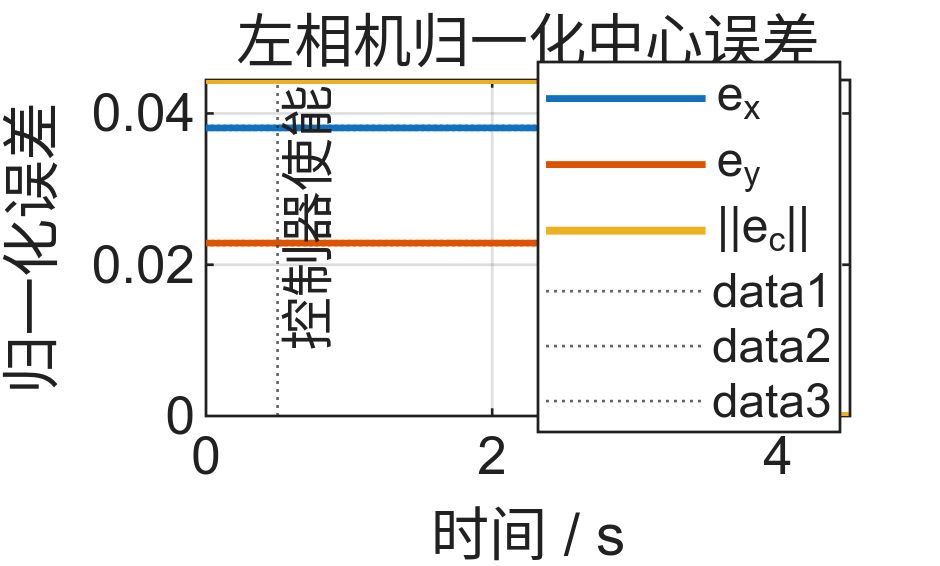


%% 图2：归一化中心误差
figure('Name','Stage 1中心误差');

plot(t,centerErrorX,'LineWidth',1.3);
hold on;
plot(t,centerErrorY,'LineWidth',1.3);
plot(t,centerErrorNorm,'LineWidth',1.5);

grid on;
xlabel('时间 / s');
ylabel('归一化误差');
title('左相机归一化中心误差');
legend( ...
    'e_x','e_y','||e_c||', ...
    'Location','best');

xline(0.5,':','控制器使能');
xline(3.0,':','目标回到中心');
xline(4.5,':','视觉无效');

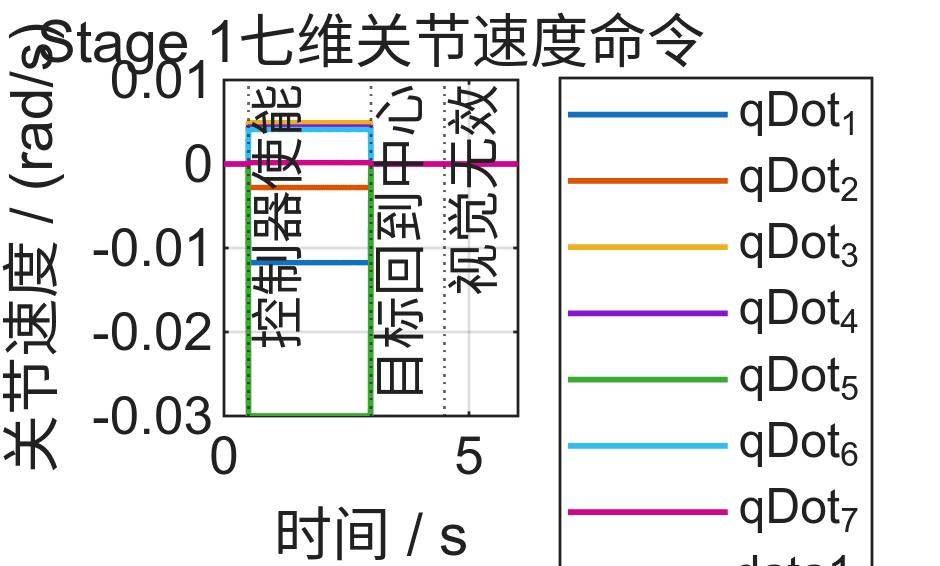


%% 图3：七个关节速度命令
figure('Name','Stage 1关节速度');

plot(t,qDot,'LineWidth',1.1);

grid on;
xlabel('时间 / s');
ylabel('关节速度 / (rad/s)');
title('Stage 1七维关节速度命令');
legend( ...
    'qDot_1','qDot_2','qDot_3','qDot_4', ...
    'qDot_5','qDot_6','qDot_7', ...
    'Location','bestoutside');

xline(0.5,':','控制器使能');
xline(3.0,':','目标回到中心');
xline(4.5,':','视觉无效');

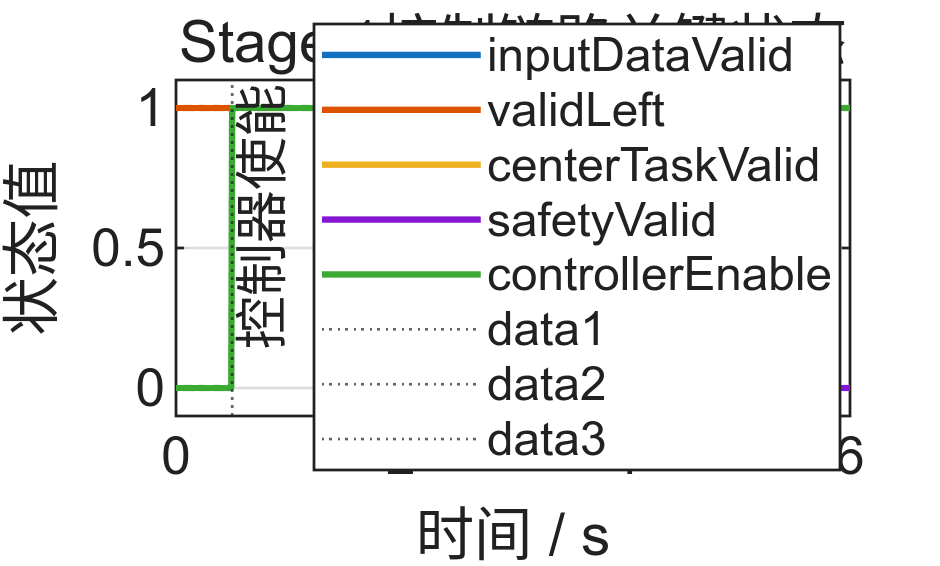


%% 图4：控制链路关键状态
% controllerStatus顺序：
% 1  inputDataValid
% 2  cameraModelValid
% 3  kinematicsValid
% 4  validLeft
% 5  validRight
% 6  depthMeasurementValid
% 7  centerTaskValid
% 8  safetyValid
% 9  ekfValid
% 10 zoomControllerValid
% 11 controllerEnable
% 12 jConditionMetric

figure('Name','Stage 1控制状态');

plot(statusTime,controllerStatus(:,1),'LineWidth',1.2);
hold on;
plot(statusTime,controllerStatus(:,4),'LineWidth',1.2);
plot(statusTime,controllerStatus(:,7),'LineWidth',1.2);
plot(statusTime,controllerStatus(:,8),'LineWidth',1.2);
plot(statusTime,controllerStatus(:,11),'LineWidth',1.2);

grid on;
xlabel('时间 / s');
ylabel('状态值');
title('Stage 1控制链路关键状态');
legend( ...
    'inputDataValid', ...
    'validLeft', ...
    'centerTaskValid', ...
    'safetyValid', ...
    'controllerEnable', ...
    'Location','best');

ylim([-0.1 1.1]);

xline(0.5,':','控制器使能');
xline(3.0,':','目标回到中心');
xline(4.5,':','视觉无效');


%% 6. 输出简单数值检查
maxJointVelocity = max(abs(qDot),[],1);

fprintf('\nStage 1仿真结果检查：\n');


Stage 1仿真结果检查：


fprintf('七个关节最大绝对速度(rad/s)：\n');

七个关节最大绝对速度(rad/s)：


disp(maxJointVelocity);

    0.0117    0.0028    0.0049    0.0044    0.0300    0.0041    0.0002




fprintf('0~0.5秒速度应为0。\n');

0~0.5秒速度应为0。


fprintf('0.5~3秒速度应出现非零值。\n');

0.5~3秒速度应出现非零值。


fprintf('3秒后目标中心误差应为0。\n');

3秒后目标中心误差应为0。


fprintf('4.5秒后视觉无效，速度应持续为0。\n');

4.5秒后视觉无效，速度应持续为0。




function signalTs = getSimulationSignal(simOut,variableName)
% 代码作用：
% 从Simulink.SimulationOutput或基础工作区中读取Timeseries信号。
%
% 输入参数含义：
% simOut：
% sim函数返回的SimulationOutput。
%
% variableName：
% To Workspace模块设置的变量名称。
%
% 输出参数含义：
% signalTs：
% 读取到的timeseries信号。

signalTs = [];

if isa(simOut,'Simulink.SimulationOutput')
    try
        signalTs = simOut.get(variableName);
    catch
        signalTs = [];
    end
end

if isempty(signalTs) && ...
        evalin('base', ...
        sprintf('exist(''%s'',''var'')',variableName)) == 1

    signalTs = evalin('base',variableName);
end

if isempty(signalTs)
    error('StereoIBVSPlot:SignalMissing', ...
        '找不到仿真输出变量：%s',variableName);
end

if ~isa(signalTs,'timeseries')
    error('StereoIBVSPlot:InvalidSignalType', ...
        '%s不是timeseries数据。',variableName);
end
end


function dataMatrix = normalizeSignalData(data,signalWidth)
% 代码作用：
% 将Simulink记录的数据统一整理成N×signalWidth矩阵。
%
% 输入参数含义：
% data：
% timeseries中的Data。
%
% signalWidth：
% 信号元素数量。
%
% 输出参数含义：
% dataMatrix：
% N×signalWidth数据矩阵。

dataMatrix = squeeze(double(data));

if isvector(dataMatrix)
    dataMatrix = dataMatrix(:);
end

if size(dataMatrix,2) == signalWidth
    return;
end

if size(dataMatrix,1) == signalWidth
    dataMatrix = dataMatrix.';
    return;
end

error('StereoIBVSPlot:SignalSizeMismatch', ...
    '信号数据无法整理为N×%d矩阵。',signalWidth);
end
